# Examen RA3L "intro Matlab"      23 août 2023  13h30 -> 15h00 (1h30) 

% Nom :  ADDA                                          /10
% Prénom :  SAb    
% Matricule :  

Dans le fichier.m fourni, il y a les données récupérées lors d'un passage du nouveau Roller Coaster du parc d'attraction "SupermegachouetteParc". Voici les vecteurs qui s'y trouvent : 

- 'pos' : les coordonnées en x et y du Roller Coaster (en complexe), soit le plan x-y

- 'z' : les différents points d'altitude de la trajectoire

- 'd' : la distance curviligne parcourue depuis le départ pour les points en z

 Sur base de ces données, répondre aux questions ci-dessous.

**1)** **Récupérez les données mesurées depuis le fichier "Data_Roller_Coaster.mat". **Ensuite, **afficher **dans une figure (voir le résultat attendu ci-dessous) : 

- la trajectoire sur le plan x-y.

- la hauteur en fonction de la distance.  

L'enregistrement de l'altitude (z) a été démarré trop tôt, les premières données ne sont donc pas pertinentes. Afin d'afficher correctement les données, **réduire le vecteur z en retirant les 5 premiers éléments de manière automatique (une solution point par point est exclue !) et stocker le résultats dans une variable 'z2'. **

*(1.5 point)*

Résultat attendu : 

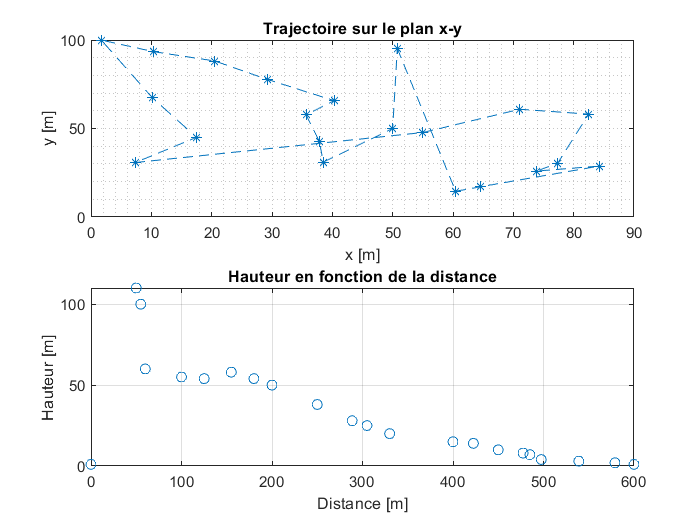

clear all 
close all
load data_roller_coaster.mat

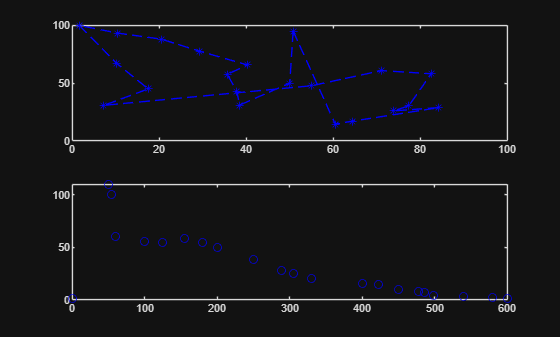

z=z(6:end);
subplot(2,1,1)
plot(real(pos),imag(pos),'--*b')

subplot(2,1,2)
plot(d,z,'ob')

**2)**  **Trouver** la plus petite distance entre 2 points consécutifs par lequel passe le Roller Coaster si l'on regarde son trajet en vue du dessus (plan x-y) et **afficher** cette distance en rouge dans le graphe de la trajectoire sur le plan x-y.

*(1 point)*

Résulat attendu :

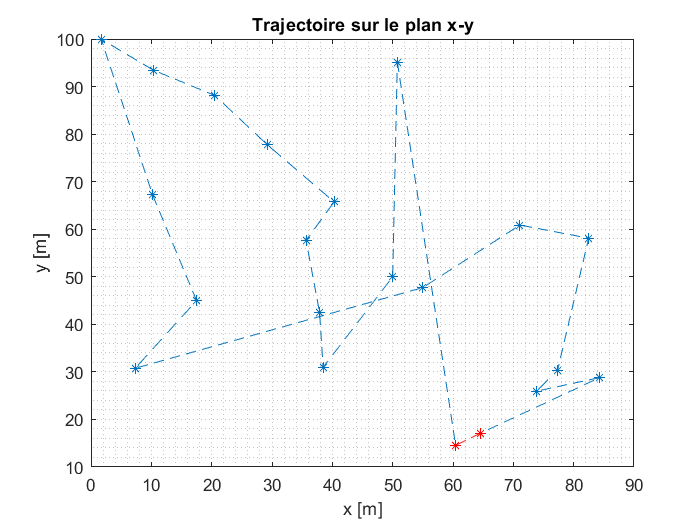

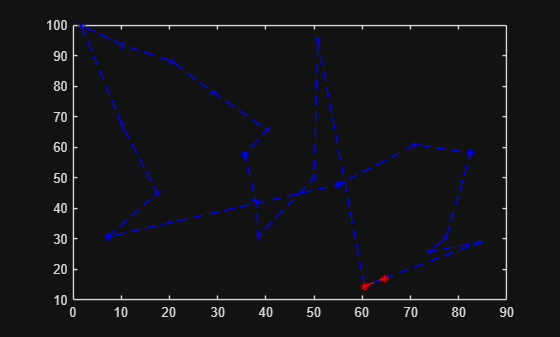

clf;
pos2=[pos pos];
a=diff(abs(pos2));
[b,idx1]=min(a);
minx=real(pos(idx1+1:idx1+2));
miny=imag(pos(idx1+1:idx1+2));
plot(real(pos),imag(pos),'--*b',minx,miny,'--*r')

**3)**  Entre le point 1 et 2 (des vecteurs d et z), on sait que la hauteur augmente proportionnellement avec la distance. Déterminer cette droite à l'aide d'un polynôme. Ensuite, calculer et afficher cette droite sur 10 points. 

Ensuite, créer deux nouveaux vecteurs (dnew et znew) qui contiennent  les 10 nouveaux poins et les points du reste de la trajectoire. 

Enfin, calculer l'altitude sur 250 points au moyen de l'interpolation (méthode **pchip**) et tracer 

- les altitudes surperposés (en bleu) à celles interpolées

- les altitudes correpondantes à la trajectoire de montée du train (en bleu) et la droite correspondante

*(3 points)*

Résultat attendu :

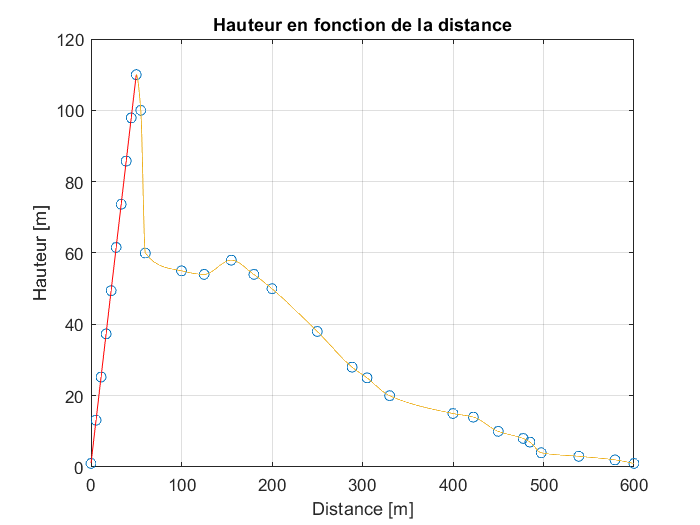

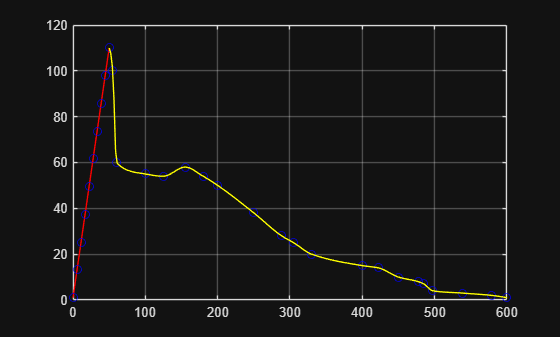

f=linspace(d(1),d(2),10);
c=polyfit(d(1:2),z(1:2),1);
e=polyval(c,f);
dnew=[f d(3:end)];
znew=[e z(3:end)];
h=linspace(d(2),d(end),250);
g=interp1(d,z,h,'pchip');


plot(f,e,'r',dnew,znew,'ob',h,g,'y')
grid

**4) Réaliser un code permettant d'afficher, **sur le graphique de la trajectoire sur le plan x-y**, les numéros correspondant à l'ordre de chaque point sur la trajectoire. **

*Aide pour une commande : "text"*

*(2.5 points)*

Résultat attendu : 

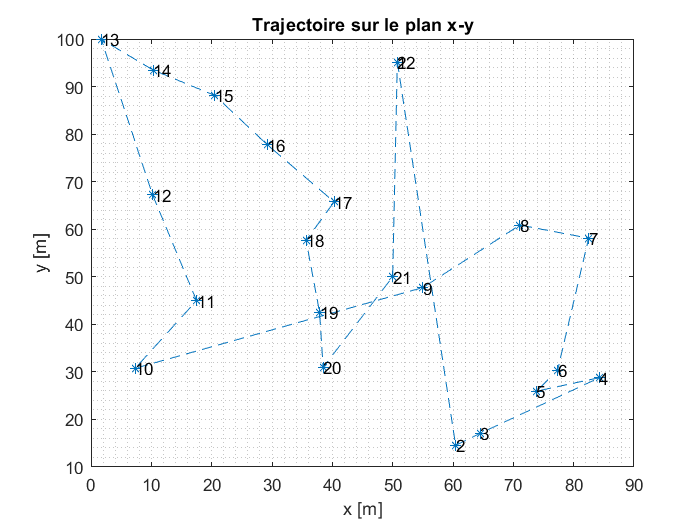

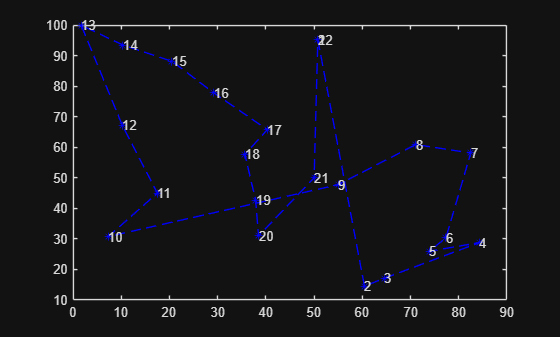

clf;
plot(real(pos),imag(pos),'--*b')
for i=1:1:length(pos)
    %k=num2str(i);
    k=sprintf('%d',i);
    text(real(pos(i)),imag(pos(i)),k)
end